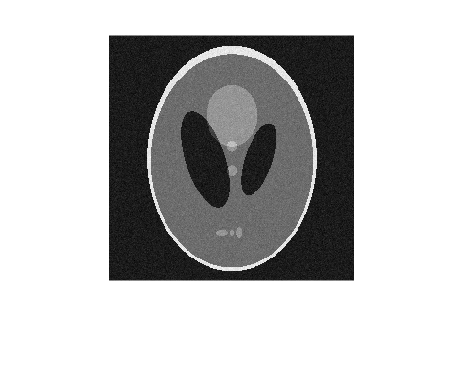


clc;
clear all;
close all;
f1 = imread('shepp256.png');
f1 = double(f1);F1=fftshift(fft2(f1));
n1 = poissrnd(80, 256, 256);
N1=fftshift(fft2(n1));

m=mean(n1(:));
v=var(n1(:));

F1poisson=F1 + N1;
f1poisson=ifft2(ifftshift(F1poisson));
im=abs(f1poisson);
%im=uint8(im);
figure(15);
imshow(im,[]);

imwrite(abs(f1poisson),'phantompoisson.jpg');

%choose pixels

%FOR TISSUE 1

windo=15;
signal=zeros(windo,windo);
background=zeros(windo,windo);
waitfor(msgbox('Choose a Tissue 1 Pixel'));
figure(16);
set(gcf,'Units','normalized','outerposition',[0 0 1 1]);
[c1,r1,~]=impixel(im,[]);
close figure 16
waitfor(msgbox('Choose a Background Pixel'));
figure(17);
set(gcf,'Units','normalized','outerposition',[0 0 1 1]);
[c2,r2,~]=impixel(im,[]);
close figure 17

signal=im(r1:r1+windo-1,c1:c1+windo-1);
background=im(r2:r2+windo-1,c2:c2+windo-1);
signal= double(signal);
background= double(background);
signal=reshape(signal,1,numel(signal));
background=reshape(background,1,numel(background));
signalmean=mean(signal);
backgroundmean=mean(background);
signalsd=std(signal);
backgroundsd=std(background);
SNR1=(signalmean/backgroundsd);

%for tissue 2
windo=15;
signal=zeros(windo,windo);
background=zeros(windo,windo);
waitfor(msgbox('Choose a Tissue 2 Pixel'));
figure(18);
set(gcf,'Units','normalized','outerposition',[0 0 1 1]);
[c1,r1,~]=impixel(im,[]);
close figure 18
waitfor(msgbox('Choose a Background Pixel'));
figure(19);
set(gcf,'Units','normalized','outerposition',[0 0 1 1]);
[c2,r2,~]=impixel(im,[]);
close figure 19

signal1=im(r1:r1+windo-1,c1:c1+windo-1);
background=im(r2:r2+windo-1,c2:c2+windo-1);
signal1= double(signal1);
background= double(background);
signal1=reshape(signal1,1,numel(signal1));
background=reshape(background,1,numel(background));
signal1mean=mean(signal1);
backgroundmean=mean(background);
signal1sd=std(signal1);
backgroundsd=std(background);
SNR2=(signal1mean/backgroundsd);

%find CNR

CNR=(signalmean-signal1mean)/(backgroundsd);